# **Projeto de Eletromagnetismo e Ondulatória**

**Integrantes:**

- Barbara Martins Damasceno    

- Maria Victória Pollupuu Cavalieri

- Rafael Ribeiro da Silva

- **Antena Transmissora**

Estamos usando uma antena de arquimedes com raio externo de 40 cm e raio interno de 20 cm. Abaixo está o código para desenhá-la:

ant1 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant1 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


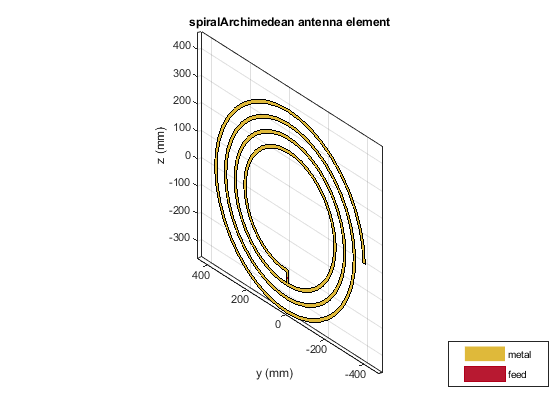

ant1.NumArms = 1;
ant1.OuterRadius = 40e-2;
ant1.InnerRadius = 20e-2;
show(ant1)

    2. **Calculando a impedância da antena em diversas frequências**

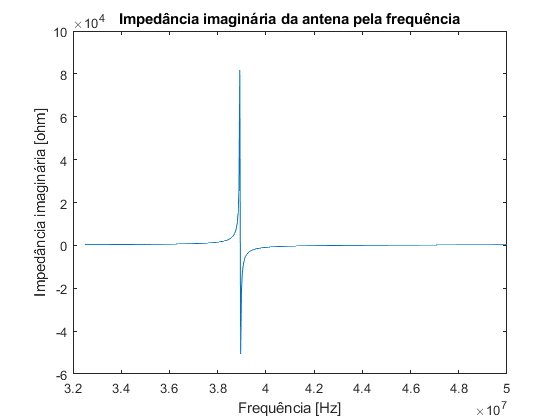

%Definindo o intervalo de frequência
f = linspace(3.25e7,5e7,500);
%Calculando a impedância
impedancia = impedance(ant1,f);
imaginario = imag(impedancia);

%Plotando a impedância imaginária em função da frequência
figure 
plot(f,imaginario)
xlabel('Frequência [Hz]')
ylabel('Impedância imaginária [ohm]')
title("Impedância imaginária da antena pela frequência")

3.** Antena Receptora**

A antena receptora é igual a antena transmissora.

ant2 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


ant2.NumArms = 1;
ant2.Tilt = 90;
ant2.OuterRadius = 40e-2;
ant2.InnerRadius = 20e-2;
show(ant2)

4. **Simulando o acoplamento das antenas**

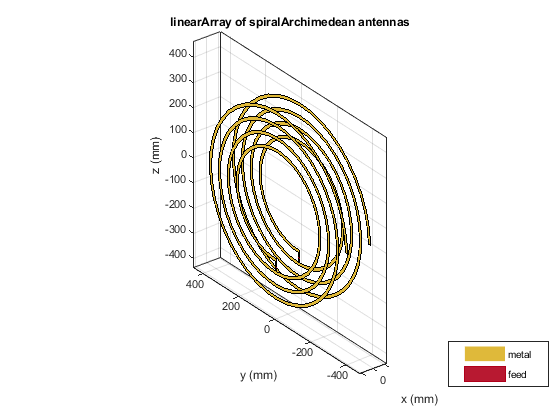

array = linearArray('Element',[ant1,ant2],'ElementSpacing',0.1);
show(array)

5. **Simulando os ganhos**

%Encontrando os ganhos com auxílio da função sparameters
ganhos = sparameters(array,f)

ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [500×1 double]
     Parameters: [2×2×500 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


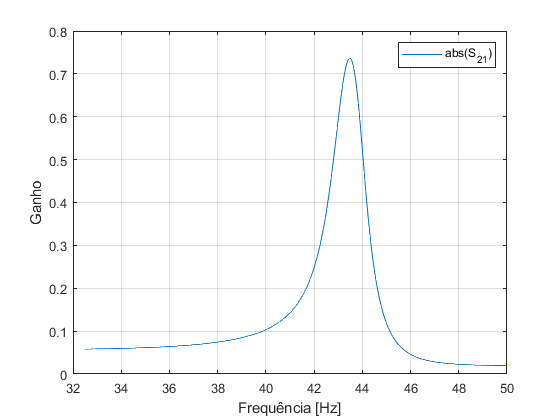


%Plotando o ganho em função da frequência
rfplot(ganhos,2,1,'abs')
xlabel('Frequência [Hz]')
ylabel('Ganho')

values = rfparam(ganhos,2,1);

%Encontrando o ganho máximo obtido e a frequência que ele ocorre
%Essa frequência é a frequência de ressonância obtida pela simulação.
ganho_maximo = abs(max(values))

ganho_maximo = 0.7363

i_max = find(abs(values) == ganho_maximo)

i_max = 314

f(i_max)

ans = 4.3477e+07

6. **Visualização em 3D**

Plotando um gráfico para entender a relação dentre frequência, distância e ganho.

g = zeros(30,500);
d = linspace(0.1, 0.6, 30);

%Calculando o ganho ponto a ponto
for n = 1:1:30
    array = linearArray('Element',[ant1,ant2],'ElementSpacing',d(1,n));
    sp = sparameters(array,f);
    g(n,:) = abs(rfparam(sp,2,1));
    
end

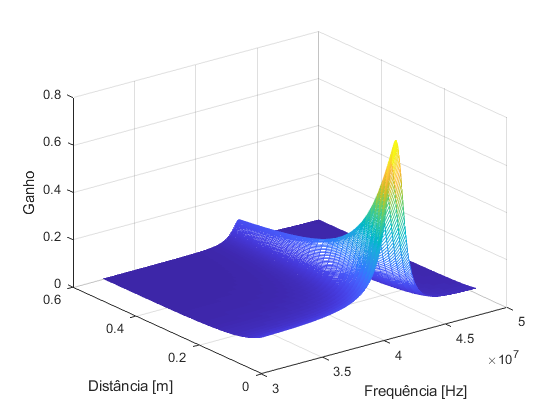

% Plotando o gráfico em 3D 
mesh(f,d,g)
xlabel('Frequência [Hz]')
ylabel('Distância [m]')
zlabel('Ganho')

8. **Unindo os dois modelos**

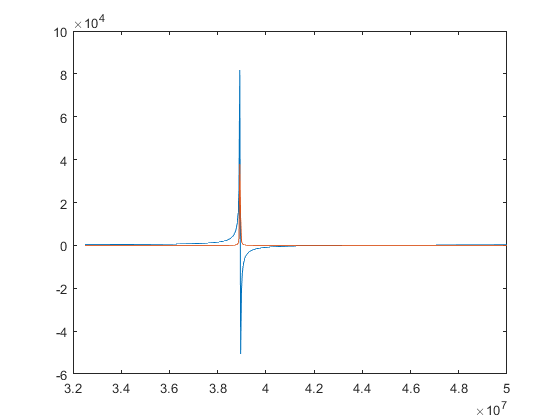

%Plotando o gráfico para descobrir a frequência de ressonância (é quando a
%impedância imaginária cruza com o 0). 
%Descobrimos a frequência ampliando o gráfico e descobrindo o valor.
plot(f,imag(impedancia),f,real(impedancia));

Para prosseguir com o exercício, usamos o modelo de um circuito RLC em série. Ele se encaixa bem na frequência de ressonância. 

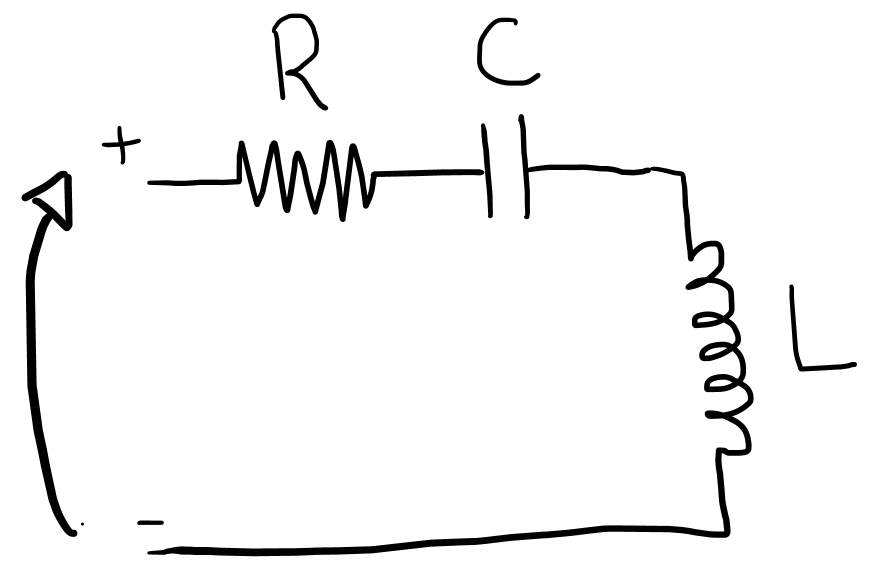

Usamos frequências próximas a de ressonância para desenvolver o modelo e encontrar os valores do capacitor e indutor, componentes relacionados a parte imaginária do modelo. 

format shortE

freq1 = 43.5471e6;
freq2 = 43.6172e6;
%Essas frequência são valores próximos a frequência de ressonância. A ideia
%é encontrar uma espécie de reta para descobrir L e C.

w1 = 2*pi*freq1;
w2 = 2*pi*freq2;

z1 = -1.18038;
z2 = 3.80925;

%Sistema de equações para encontrar L e C:
%Eq 1: w1*L - 1/(w1*C) = z1
%Eq 2: w2*L - 1/(w2*C) = z2
A = [w1 -1/w1;w2 -1/w2];
B = [z1;z2];

X = linsolve(A,B);


L = X(1)

L =    5.6666e-06


C = 1/(X(2))

C =    2.3554e-12


%Conferindo se nosso modelo é próximo a realidade, ou seja, se a frequência
%obtida é próxima da frequência de ressonância que encontramos via
%simulação.

wr = 1/sqrt(L*C)

wr =    2.7372e+08


freq_r = wr/(2*pi)

freq_r =    4.3564e+07



%A frequencia de ressonância encontrada tem precisão de 3 casas decimais,
%em comparação com a frequência de ressonância encontrada por simulação.

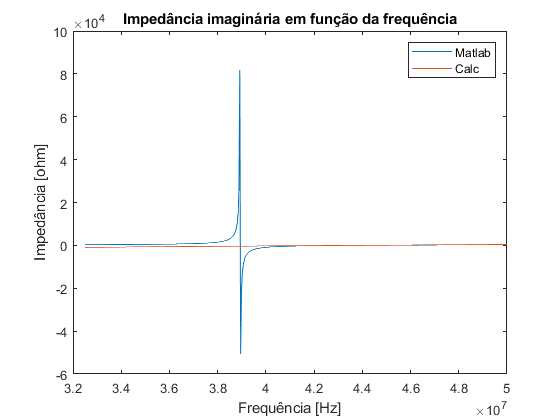

w = f*2*pi;
Imp = w.*(L*1j) + 1./(w.*(C*1j));

%Comparando a impedância imaginária do nosso modelo (base circuito RLC em
%série) com a impedância imaginária da simulação.
plot(f,imag(impedancia),f,imag(Imp))
legend('Matlab','Calc')
xlabel('Frequência [Hz]')
ylabel('Impedância [ohm]')
title("Impedância imaginária em função da frequência")

%Note que próximo ao 0 e na frequência de ressonância, ambas as funções
%estão iguais.

%Pegando a parte real da nossa impedância calculada para ser nosso resistor
R = real(impedance(ant1,freq_r))

R =    7.7355e-01


%Tensão para alimentar o modelo. 
U = 1;

%Encontrando o ganho na frequência de ressonância encontrada a partir do
%modelo do circuito RLC em série
gzinho = zeros(1,30);
for n = 1:1:30
    
    array = linearArray('Element',[ant1,ant2],'ElementSpacing',d(1,n));
    sp = sparameters(array,freq_r);
    gzinho(1,n) = abs(rfparam(sp,2,1));
    
end

%Encontrando a constante k da indutância mútua que funciona como um ajuste.
% M = k * (raiz (L1 * L2))
k = zeros(1,30);
for n = 1:1:30
    kzinho = sqrt((gzinho(1,n)*R^2)/((-gzinho(1,n) + 1)*wr^2))*(1/L);
    k(1,n) = kzinho;
end

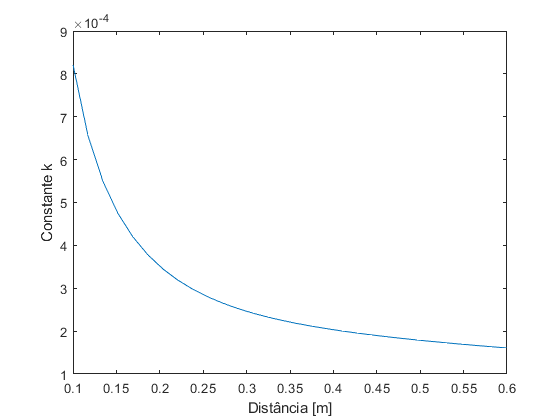

%Plotando a constante k em função da distância
plot(d,k)
xlabel('Distância [m]')
ylabel('Constante k')

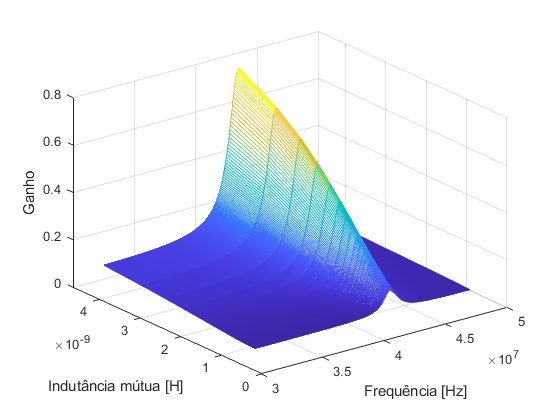

%Plotando o gráfico em 3D da frequência, ganho e indutância mútua.
M = k*L;
mesh(f,M,g)
xlabel('Frequência [Hz]')
ylabel('Indutância mútua [H]')
zlabel('Ganho')